Para Ts grande

Diseñamos C para una F buscada

### El mejor control(eficiente):

C(z) con mismo orden en num y denominador

Diferencia de ordenes num y denominador de Dy F iguales

F tiene un polo las que cero

clc 
clear
runTime=2.5; %Tiempo que dura la simulacion de Simulink

### Periodo de Muestreo

Ts=0.05; %buscamos un Ts que haga que Pd sea inversamente estable
ts=Ts;

### Modelo de Planta

%%Modelado
s=tf('s');
z=tf('z', Ts);
Km=8.2897e-02;
Tm= 6.0718e-02;
Tf=0.18;
P = Km/(Tm*s+1)/(Tf*s+1);
Pd=c2d(P, Ts, 'zoh')

Pd =
 
  0.006663 z + 0.004618
  ----------------------
  z^2 - 1.196 z + 0.3325
 
Sample time: 0.05 seconds
Discrete-time transfer function.



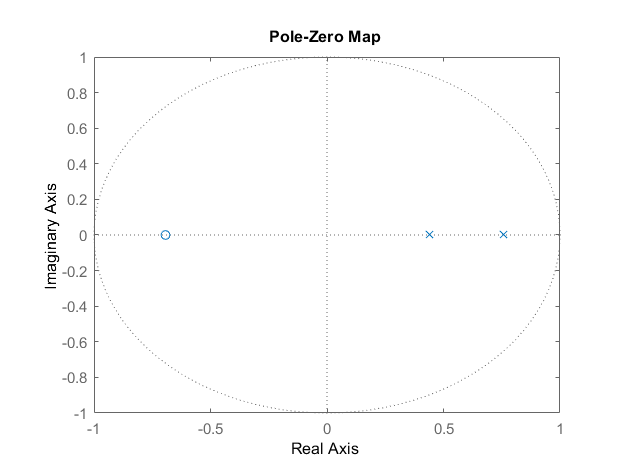

pzmap(Pd)% O dentro del circulo unidad -> estable

En este caso,el denominador tiene 2 polos mas que ceros asi que usaremos un deadbeat de 2º orden como optimo

### Primer Orden: Fd =1/z

Fd=1/z;
% Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
Cd=minreal(Fd/Pd/(1-Fd));
%PlotSimulation("PrimerOrden","Control_deadbeat_sim.slx")


Para ordenes mayores que uno añadimos ceros iguales a los ceros de la planta

### Segundo orden Fd= (z −α )/(1−α )/z^2

[zPd,pPd,kPd]=zpkdata(Pd,'v')

zPd = -0.6931

pPd =     0.7575
    0.4389


kPd = 0.0067

alfa=zPd(1);
Fd=(z-alfa)/(1-alfa)/z^2;
% Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
Cd=minreal(Fd/Pd/(1-Fd));
Crd=Cd

Crd =
 
  88.64 z^2 - 106.1 z + 29.47
  ---------------------------
    z^2 - 0.5906 z - 0.4094
 
Sample time: 0.05 seconds
Discrete-time transfer function.



PlotSimulation("SegundoOrden","Control_deadbeat_sim.slx")

result =   Run with properties:

                         id: 9208
                       Name: 'SegundoOrden 2 Control_deadbeat_sim'
                Description: ''
                        Tag: ''
                DateCreated: 09-Oct-2021 14:07:52
                   RunIndex: 2
                SignalCount: 3
                      Model: 'Control_deadbeat_sim'
                    SimMode: 'normal'
                  StartTime: 0
                   StopTime: 2.5000
                  SLVersion: 'Simulink 10.3 (R2021a)'
               ModelVersion: '1.5'
                     UserID: ''
                MachineName: 'DESKTOP-DF23KMF'
                   Platform: 'PCWIN64'
                   TaskName: ''
                 SolverType: 'Variable-Step'
                 SolverName: 'ode45'
             SolverStepSize: '1e-05'
                     Status: 'ReachedStopTime'
            StopEventSource: ''
       StopEventDescrip

ans =   Run with properties:

                         id: 9208
                       Name: 'SegundoOrden 2 Control_deadbeat_sim'
                Description: ''
                        Tag: ''
                DateCreated: 09-Oct-2021 14:07:52
                   RunIndex: 2
                SignalCount: 3
                      Model: 'Control_deadbeat_sim'
                    SimMode: 'normal'
                  StartTime: 0
                   StopTime: 2.5000
                  SLVersion: 'Simulink 10.3 (R2021a)'
               ModelVersion: '1.5'
                     UserID: ''
                MachineName: 'DESKTOP-DF23KMF'
                   Platform: 'PCWIN64'
                   TaskName: ''
                 SolverType: 'Variable-Step'
                 SolverName: 'ode45'
             SolverStepSize: '1e-05'
                     Status: 'ReachedStopTime'
            StopEventSource: ''
       StopEventDescriptio

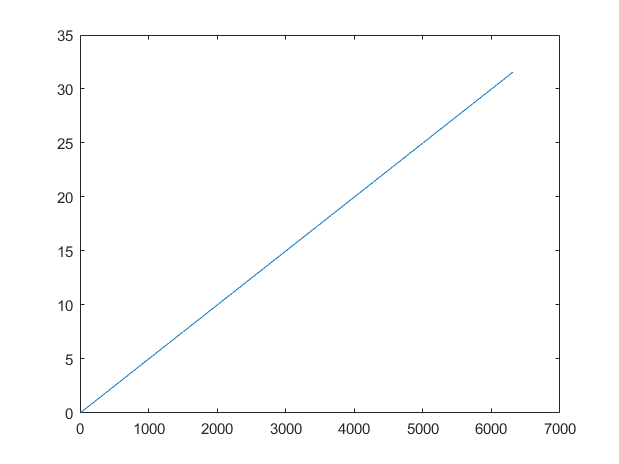

result =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×6314 double]
              YData: [1×6314 double]
              ZData: [1×0 double]

  Show all properties


ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×6314 double]
              YData: [1×6314 double]
              ZData: [1×0 double]

  Show all properties


load v_Velocidad_rampa.mat Velocidad

RunSIM_VELOCIDAD();

### Tercer orden Fd= (z −α1 )(z −α2 )/(1−α1 )/(1−α2 )/z^2

% [zPd,pPd,kPd]=zpkdata(Pd,'v')
% alfa1=zPd(1);
% alfa2=zPd(2);
% Fd=(z-alfa1)*(z-alfa2)/(1-alfa1)/(1-alfa2)/z^2;
% % Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
% Cd=minreal(Fd/Pd/(1-Fd));
%Crd=Cd
% PlotSimulation("TercerOrden","Control_deadbeat_sim.slx")
